# [使用可解释的技术进行音乐流派分类](https://ww2.mathworks.cn/help/deeplearning/ug/investigate-audio-classifications-using-interpretability-techniques.html)

此示例说明如何使用小波时间散射和音频数据存储对音乐片段的类型进行分类。 在小波散射中，数据通过一系列小波变换、非线性和平均来传播，以产生数据的低方差表示。 然后将这些低方差表示用作分类器的输入。

## 数据准备

### GTZAN 数据集

在该研究中使用的数据集是GTZAN 流派集合。数据以大约 1.2 GB 的压缩 tar 存档形式提供。 未压缩的数据集需要大约 3 GB 的磁盘空间。 从参考资料中提供的链接中提取压缩的 tar 文件会创建一个包含十个子文件夹的文件夹。 每个子文件夹都以其包含的音乐样本类型命名。 流派是：蓝调、古典、乡村、迪斯科、嘻哈、爵士、金属、流行、雷鬼和摇滚。 每个流派有 100 个示例，每个音频文件包含约 30 秒的数据，采样频率为 22050 Hz。 在原始论文中，作者使用了许多时域和频域特征，包括从每个音乐示例中提取的梅尔频率倒谱 (MFC) 系数和高斯混合模型 (GMM) 分类，以实现 61% 的准确率 [ 7]。随后，深度学习网络已应用于此数据。 在大多数情况下，这些深度学习方法由卷积神经网络 (CNN) 组成，其中 MFC 系数或频谱图作为深度 CNN 的输入。 这些方法的性能达到了 84% 左右 [4]。 具有频谱图时间片的 LSTM 方法产生了 79% 的准确度，时域和频域特征与集成学习方法 (AdaBoost) 相结合，在测试集上产生了 82% 的准确度 [2][3]。 最近，一种稀疏表示机器学习方法达到了大约 89% 的准确率 [6]。

### 音频数据准备

第一步是下载 GTZAN 流派合集 [7][8]。 此示例中的说明假定您将数据集下载到 MATLAB® 中的临时目录 tempdir。 如果您选择将数据下载到与 tempdir 不同的文件夹中，请在后续说明中更改目录名称。 使用 gunzip 下载并解压缩数据集。 然后使用 untar 提取 tar 文件的内容。 文件夹 genres 在 tempdir 中创建。 流派内部有十个子文件夹，每个子文件夹对应一种音乐流派。

% addpath('utils\');
run("init");
data_dir = fullfile(work_dir, 'data', 'brain', 'auditory');
workspace_dir = fullfile(data_dir, 'process_music_fMRI');
classification_dataset_dir = fullfile(data_dir, 'classification_dataset');  if ~exist(classification_dataset_dir, 'dir'); mkdir(classification_dataset_dir); end
wave_dir = fullfile(workspace_dir, 'genres_wav15s');
tmp_dir = fullfile(data_dir, 'tmp');  % 存放临时文件（加速）
if ~exist(tmp_dir, 'dir'); mkdir(tmp_dir); end

% 准备分类用的训练类脑模型所使用的训练集合测试集
train_info = load(fullfile(workspace_dir, "genres_forExp", "ExpTrnOrder.mat"));
train_info = train_info.TrnOrd;
train_dir = fullfile(classification_dataset_dir, 'train');  % 480 个音频文件
% if ~exist(train_dir, 'dir'); mkdir(train_dir); end  

val_info = load(fullfile(workspace_dir, "genres_forExp", "ExpValOrder.mat"));
val_info = val_info.ValOrd;
val_dir = fullfile(classification_dataset_dir, 'val');  % 240 个音频文件

if ~exist(train_dir, 'dir')
    for i = 1 : size(train_info, 1)
        for j = 1 : size(train_info, 2)
            cur_audio_name = train_info{i, j};
            name_splits = split(cur_audio_name, '.');
            cur_audio_dir = fullfile(train_dir, name_splits{1});
            if ~exist(cur_audio_dir, 'dir'); mkdir(cur_audio_dir); end
            copyfile(fullfile(wave_dir, cur_audio_name), cur_audio_dir);
        end
    end
    for i = 1 : size(val_info, 1)
        for j = 1 : size(val_info, 2)
            cur_audio_name = val_info{i, j};
            name_splits = split(cur_audio_name, '.');
            cur_audio_dir = fullfile(val_dir, name_splits{1});
            if ~exist(cur_audio_dir, 'dir'); mkdir(cur_audio_dir); end
            copyfile(fullfile(wave_dir, cur_audio_name), cur_audio_dir);
        end
    end
end

### 训练数据准备

ads = audioDatastore(train_dir, IncludeSubfolders=true,LabelSource="foldernames"); [adsTrain,adsValidation] = splitEachLabel(ads,0.8,0.2); % 使用固定的训练集合测试集划分

addpath('utils');

adsTrain = audioDatastore(train_dir, IncludeSubfolders=true,LabelSource="foldernames");
labelTable = countEachLabel(adsTrain);
classes = labelTable.Label;
numClasses = size(labelTable,1);

adsValidation = audioDatastore(val_dir, IncludeSubfolders=true,LabelSource="foldernames");

overlapPercentage = 75;

[trainFeatures,trainLabels] = helperAudioPreprocess(adsTrain,overlapPercentage);
[validationFeatures,validationLabels,segmentsPerFile] = helperAudioPreprocess(adsValidation,overlapPercentage);

## 类脑音频识别模型

### 模型定义

try
    pretrainedNetwork = vggish;
catch ME  % 如果path路径下不存在vggish模型，则下载并添加到path路径下
    vggish_model_path = fullfile(raw_url, 'vggish.zip');
    unzip(vggish_model_path, data_dir);
    addpath(fullfile(data_dir, 'vggish'));
    pretrainedNetwork = vggish;
end

% deepNetworkDesigner(pretrainedNetwork);
lgraph = layerGraph(pretrainedNetwork.Layers);

lgraph = removeLayers(lgraph,"regressionoutput");
lgraph.Layers(end);

lgraph = addLayers(lgraph,fullyConnectedLayer(numClasses,Name="FCFinal"));
lgraph = addLayers(lgraph,softmaxLayer(Name="softmax"));
lgraph = addLayers(lgraph,classificationLayer(Name="classOut"));

lgraph = connectLayers(lgraph,"EmbeddingBatch","FCFinal");
lgraph = connectLayers(lgraph,"FCFinal","softmax");
lgraph = connectLayers(lgraph,"softmax","classOut");

miniBatchSize = 128;
options = trainingOptions("adam", ...
    MaxEpochs=5, ...  % 
    MiniBatchSize=miniBatchSize, ...
    InitialLearnRate = 0.001, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=2, ...
    LearnRateDropFactor=0.5, ...
    ValidationData={validationFeatures,validationLabels}, ...
    ValidationFrequency=50, ...
    Shuffle="every-epoch");

### 模型训练

% deepNetworkDesigner(lgraph);
% classification accuracy: 85%
model_path = fullfile(tmp_dir, 'net.mat');
if ~exist(model_path, 'file')
    [net, netInfo] = trainNetwork(trainFeatures, trainLabels, lgraph,options);
    save(model_path, 'net');
else
    net_tmp = load(model_path); net = net_tmp.net;
end

### 获得各层模型的激活

trainFeatures: 96*64*1*28320(48*10*59), a audio file(96*64*1*59)

act4_2_train = activations(net, trainFeatures, 'conv4_2');    % 12*8*512 * 28320(48image * 10class * 59)
act4_2_val = activations(net, validationFeatures, 'conv4_2'); % 12*8*512 * 3540 (6image  * 10class * 59)
audio_features = cat(4, act4_2_train, act4_2_val);
save(fullfile(tmp_dir, 'audio_feature.mat'), 'audio_features', '-v7.3');

## 测试

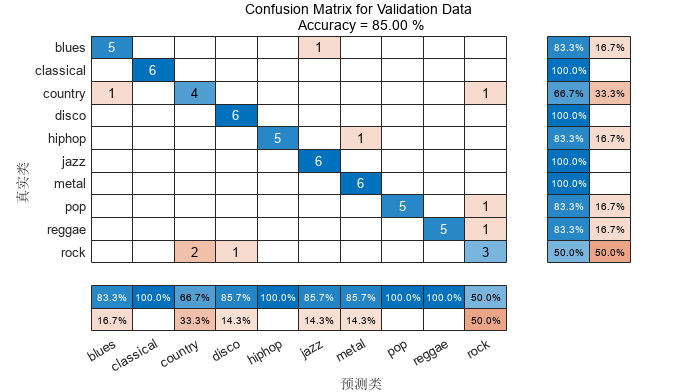

[validationPredictions,validationScores] = classify(net,validationFeatures);
idx = 1;
validationPredictionsPerFile = categorical;
for ii = 1:numel(adsValidation.Files)
    validationPredictionsPerFile(ii,1) = mode(validationPredictions(idx:idx+segmentsPerFile(ii)-1));
    idx = idx + segmentsPerFile(ii);
end

accuracy = mean(validationPredictionsPerFile==adsValidation.Labels)*100;  % disp(accuracy);

figure(Units="normalized",Position=[0.2 0.2 0.5 0.5]);
cm = confusionchart(adsValidation.Labels,validationPredictionsPerFile);
cm.Title = sprintf("Confusion Matrix for Validation Data \nAccuracy = %0.2f %%", accuracy);
cm.ColumnSummary = "column-normalized";
cm.RowSummary = "row-normalized";
% 导出图像
exportgraphics(gcf, fullfile(figs_dir, 'confusion_matrix.pdf'));

### 可视化预测

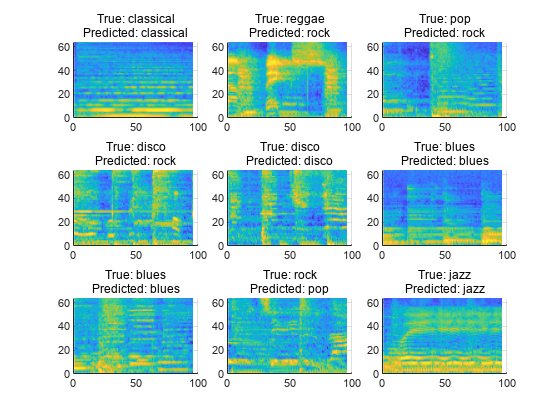

numImages = 9;
idxSubset = randi(numel(validationLabels),1,numImages);

viewingAngle = [90 -90];

figure
t1 = tiledlayout("flow",TileSpacing="compact");
for i = 1:numImages
    img = validationFeatures(:,:,:,idxSubset(i));
    YPred = validationPredictions(idxSubset(i));
    YTrue = validationLabels(idxSubset(i));

    nexttile
    surf(img,EdgeColor="none")
    view(viewingAngle)
    title({"True: " + string(YTrue),"Predicted: " + string(YPred)},interpreter= "none")
end
colormap parula
exportgraphics(gcf, fullfile(figs_dir, 'predicted_results.pdf'));

### 预测分析

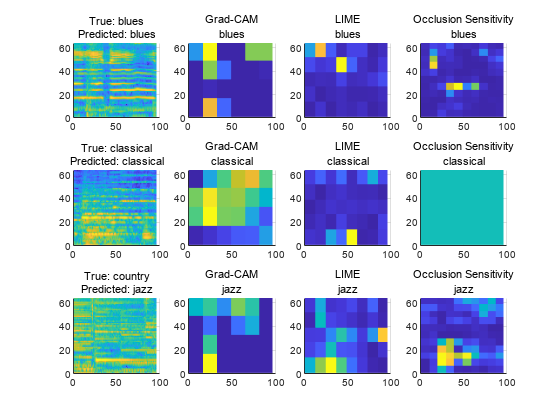

viewingAngle = [90 -90];
imgIdx = [250 500 750];
numImages = length(imgIdx);

figure
t2 = tiledlayout(numImages,4,TileSpacing="compact");
for i = 1:numImages

    img = validationFeatures(:,:,:,imgIdx(i));
    YPred = validationPredictions(imgIdx(i));
    YTrue = validationLabels(imgIdx(i));

    mapClass = YPred;

    mapGradCAM = gradCAM(net,img,mapClass, ...
        OutputUpsampling="nearest");

    mapLIME = imageLIME(net,img,mapClass, ...
        OutputUpsampling="nearest", ...
        Segmentation="grid");

    mapOcclusion = occlusionSensitivity(net,img,mapClass, ...
        OutputUpsampling="nearest");

    maps = {mapGradCAM,mapLIME,mapOcclusion};
    mapNames = ["Grad-CAM","LIME","Occlusion Sensitivity"];

    helperPlotMaps(img,YPred,YTrue,maps,mapNames,viewingAngle,mapClass)
end

exportgraphics(gcf, fullfile(figs_dir, 'investigate_predictions.pdf'));

### 指定类别的预测分析

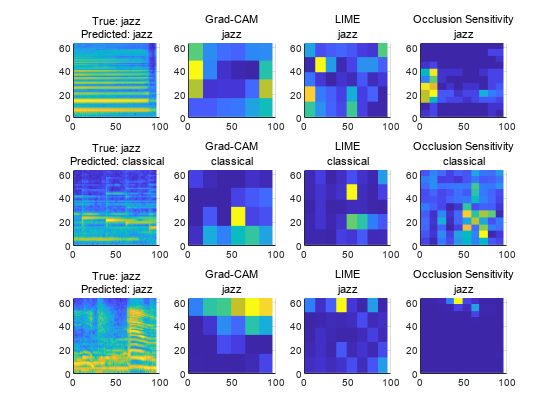

classToInvestigate = "jazz";
idxClass = find(classes == classToInvestigate);
idxSubset = validationLabels==classes(idxClass);

subsetLabels = validationLabels(idxSubset);
subsetImages = validationFeatures(:,:,:,idxSubset);
subsetPredictions = validationPredictions(idxSubset);

imgIdx = [25 50 100];
numImages = length(imgIdx);


viewingAngle = [90 -90];

figure
t3 = tiledlayout(numImages,4,"TileSpacing","compact");
for i = 1:numImages

    img = subsetImages(:,:,:,imgIdx(i));
    YPred = subsetPredictions(imgIdx(i));
    YTrue = subsetLabels(imgIdx(i));

    mapClass = YPred;

    mapGradCAM = gradCAM(net,img,mapClass, ...
        OutputUpsampling="nearest");

    mapLIME = imageLIME(net,img,mapClass, ...
        OutputUpsampling="nearest", ...
        Segmentation="grid");

    mapOcclusion = occlusionSensitivity(net,img,mapClass, ...
        OutputUpsampling="nearest");

    maps = {mapGradCAM,mapLIME,mapOcclusion};
    mapNames = ["Grad-CAM","LIME","Occlusion Sensitivity"];

    helperPlotMaps(img,YPred,YTrue,maps,mapNames,viewingAngle,mapClass)
end
exportgraphics(gcf, fullfile(figs_dir, 'specific_class.pdf'));

### 分析错误分类

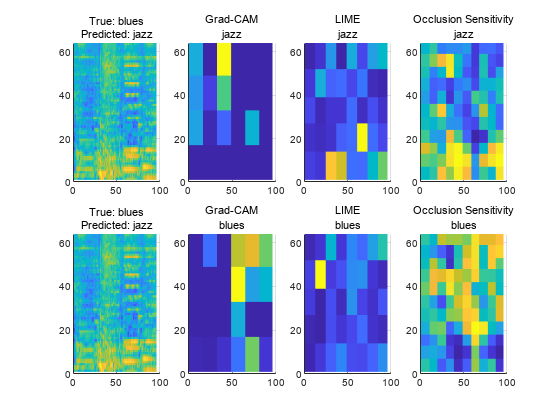

trueClass = "blues";
predictedClass = "jazz";

incorrectIdx = find(validationPredictions == predictedClass & validationLabels' == trueClass);

idxToInvestigate = incorrectIdx(1);
YPred = validationPredictions(idxToInvestigate);
YTrue = validationLabels(idxToInvestigate);


figure
t4 = tiledlayout(2,4,"TileSpacing","compact");
img = validationFeatures(:,:,:,idxToInvestigate);

for mapClass = [YPred, YTrue]

    mapGradCAM = gradCAM(net,img,mapClass, ...
        OutputUpsampling="nearest");

    mapLIME = imageLIME(net,img,mapClass, ...
        OutputUpsampling="nearest", ...
        Segmentation="grid");

    mapOcclusion = occlusionSensitivity(net,img,mapClass, ...
        OutputUpsampling="nearest");

    maps = {mapGradCAM,mapLIME,mapOcclusion};
    mapNames = ["Grad-CAM","LIME","Occlusion Sensitivity"];

    helperPlotMaps(img,YPred,YTrue,maps,mapNames,viewingAngle,mapClass)
end

exportgraphics(gcf, fullfile(figs_dir, 'investigate_misclassifications.pdf'));